%Test original MIND
clear all, close all;
folder = {'descriptor','external_code','ssim'};
for it=1:length(folder)
    p = genpath(folder{it});
    addpath(p);
end
descriptor = 'LSSD';  %  'LGHD'|'EHD'|'PCEHD' | 'ELGHD' | 'HOG' | 'LSSD' | 'EMD'
% use classic = 1 to use descriptors above (not MIND)
%folder = 'test_images/'
folderTh = 'M3FD2/Ir/';
folderVis = 'M3FD2/Vis/';
imagesRgb = dir(folderVis);
imagesLwir = dir(folderTh);
numbs = randi(400,80,1);
step = 20;
miss = 0; i = 0; show = 1; classic = 0, sharpen = 0;

classic = 0

missTab = int16.empty(200,0);
missAmount = single.empty(200,0);
totError = single.empty(200,0);
timeExec = single.empty(200,0);
pointsStat = zeros([200,4,1],"uint16");
pointsStatMiss = zeros([200,4,1],"uint16");
nbImages = 0;
k =  50;
maxIndex = min(nbImages*step+4+k,length(imagesLwir));
ws = 40;
k

k = 50

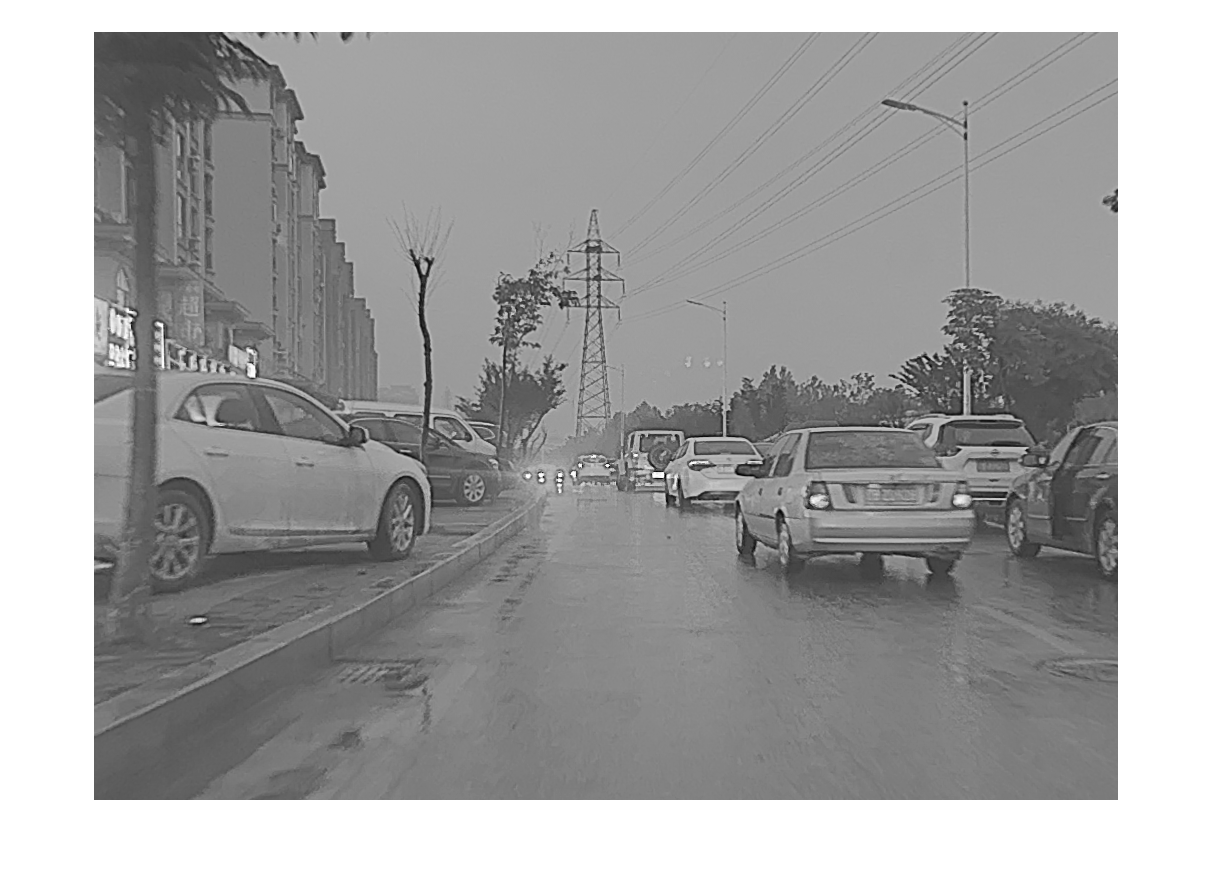

nameRgb = imagesRgb(k).name;
nameLwir = imagesLwir(k).name;
im_rgb = rescale(double(im2gray(imread(strcat(folderVis,nameRgb)))));
im_lwirori = rescale(double(im2gray(imread(strcat(folderTh,nameLwir)))));
im_lwirori = imtranslate(im_lwirori,[40 40]);
imfft1 = fftshift(fft2(im_rgb));
imfft2 = fftshift(fft2(im_lwirori));
phasergb = angle(imfft1);
absrgb = abs(imfft1);
abslwir = abs(imfft2);
phaselwir = angle(imfft2);
frgb = ifft2(ifftshift(absrgb.*(exp(1i*phaselwir))));
flwir = ifft2(abslwir.*(exp(1i*phasergb)));
% M = im_rgb*im_lwirori'
% im_vlwir = rescale(M*im_rgb);
figure, imshow(im_rgb);

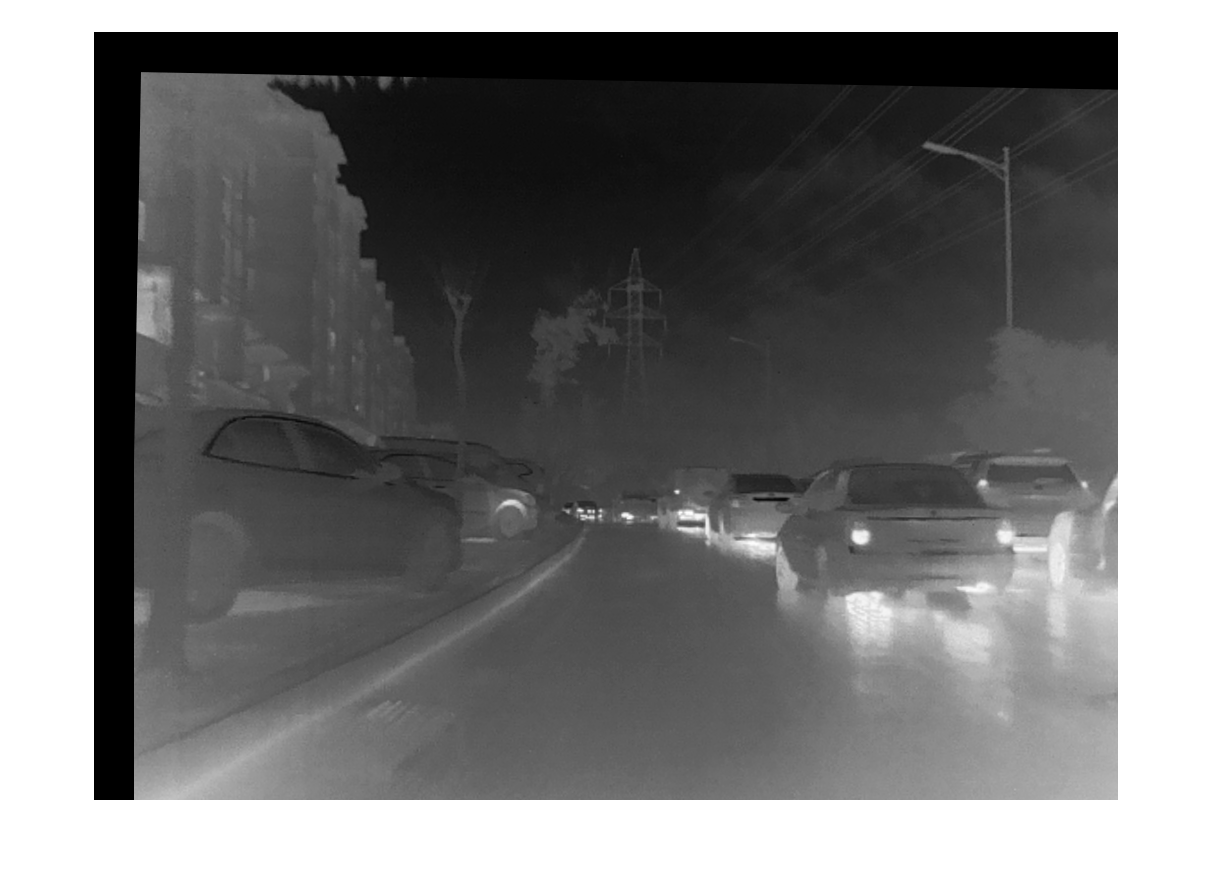

figure, imshow(im_lwirori);

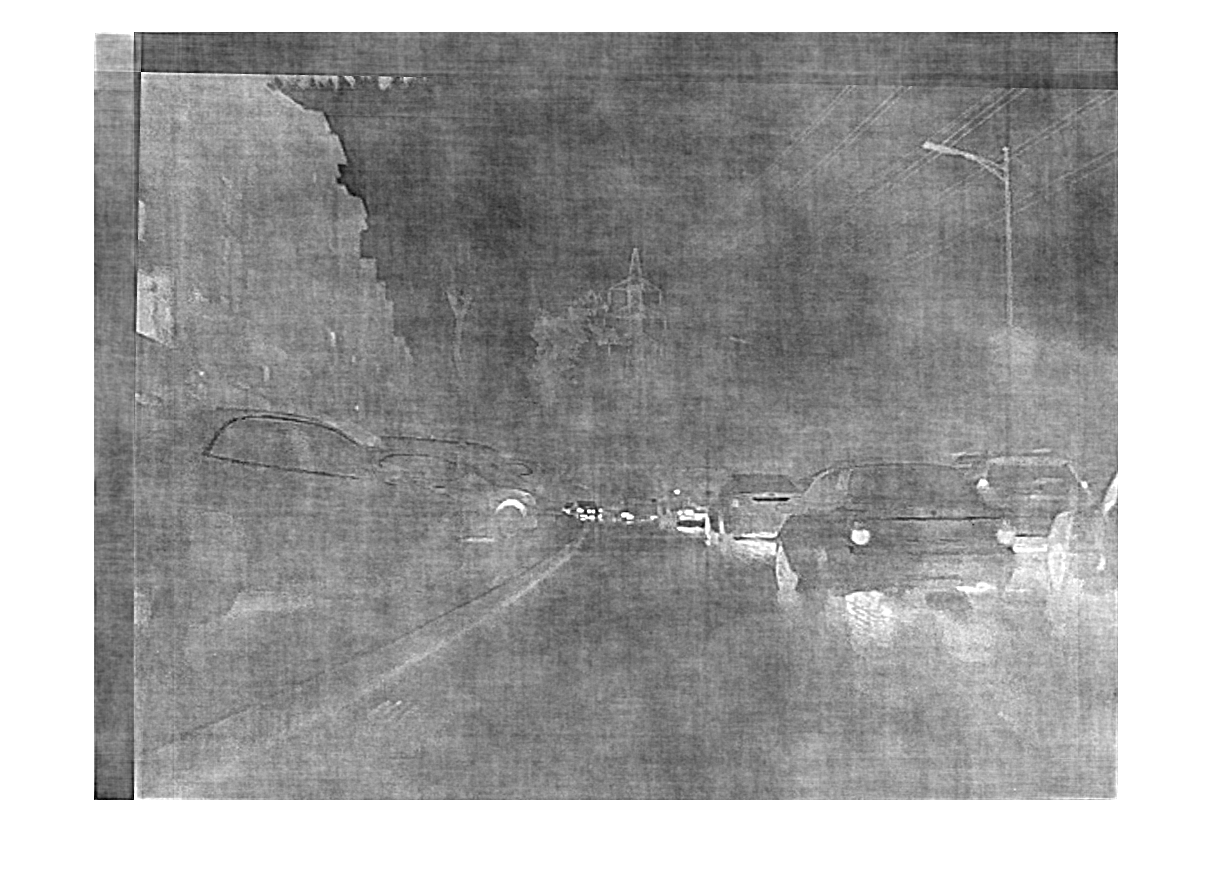

%figure, imshow(M)
figure, imshow(abs(frgb));

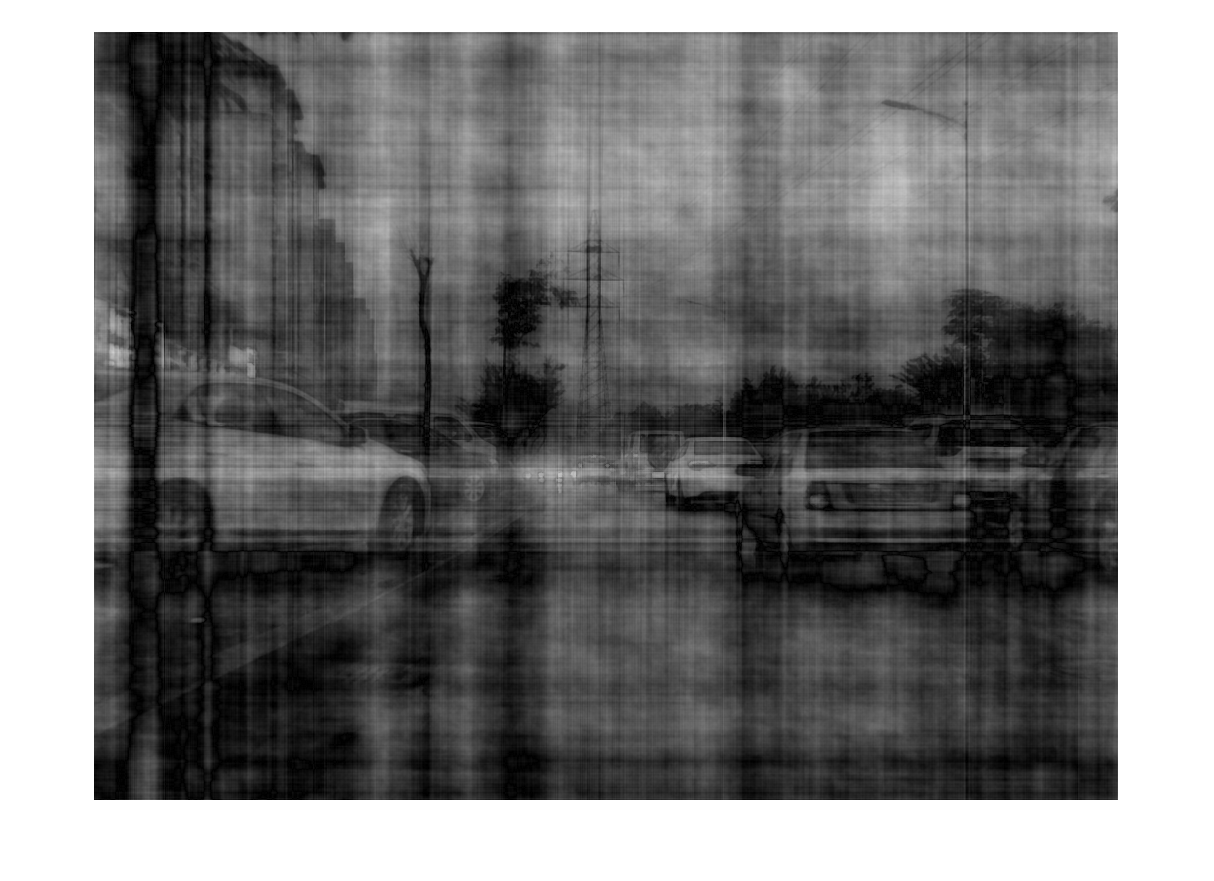

figure, imshow(abs(flwir));